%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ENG EC 503 (Ishwar) Fall 2023
% HW 4.1
% <Demetrios Kechris dkechris@bu.edu>
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear all; clc;
rng('default')  % For reproducibility of data and results


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.1(a)
% create data set, mean, cov, average cov
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%data is row1 = x, row2 = y
D = [-1 -1; -1/2 -1/8; 0 0; 1/2 1/8; 1 1]

D =    -1.0000   -1.0000
   -0.5000   -0.1250
         0         0
    0.5000    0.1250
    1.0000    1.0000


Dxy = transpose(D)

Dxy =    -1.0000   -0.5000         0    0.5000    1.0000
   -1.0000   -0.1250         0    0.1250    1.0000


Dx = Dxy(1,:)

Dx =    -1.0000   -0.5000         0    0.5000    1.0000


Dy = Dxy(2,:)

Dy =    -1.0000   -0.1250         0    0.1250    1.0000


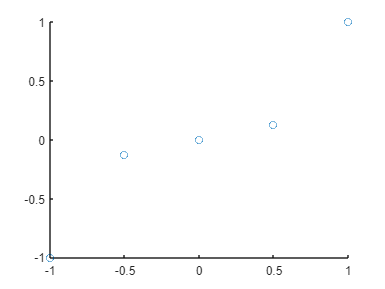


% visualize data
scatter(Dx,Dy)


%calc means
meanDx = XYmean(Dx)

meanDx = 0

meanDy = XYmean(Dy)

meanDy = 0

meanDxy = XYmean(Dxy)

meanDxy =      0
     0



%calc cross cov
Dx_ccov = XYcov(Dx)

Dx_ccov = 0.5000

Dy_ccov = XYcov(Dy)

Dy_ccov = 0.4062

Dxy_ccov = XYcov(Dxy)

Dxy_ccov =     0.5000    0.4250
    0.4250    0.4062



% Dave cov
%Dtot_ccov = (size(Dneg,2)/size(Dtot,2)*Dneg_ccov) + (size(Dpos,2)/size(Dtot,2)*Dpos_ccov)

% Wols = Sx ^-1 * Sxy
wols = Dx_ccov ^-1 * Dxy_ccov 

wols =     1.0000    0.8500
    0.8500    0.8125



% Bols = muy - (wols)T * mx
bols = meanDy - transpose(wols) * meanDx

bols =      0     0
     0     0



% MSE = Sy - Syx*Sx^-1*Sxy

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4.1(b)
% Compute wLDA, bLDA, and the CCR of the LDA classifier.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Dtot_wlda = calc_wlda(Dneg, Dpos)
%Dtot_blda = calc_blda(Dneg, Dpos, Dtot_wlda)
%Dtot_wblda = [Dtot_wlda; Dtot_blda]

function mean = XYmean(data)
% takes in an array of data (x1; x2; x3; ...)
% returns the mean of each column
    mean = zeros(size(data,1),1);
    for i = 1:size(data,1)
        Imean = sum(data(i,:))/size(data,2);
        mean(i,1) = Imean;
    end
end

function data_cov = XYcov(data)
% takes in an array of data (x1; x2; x3; ...)
% returns covariance of the data, dxd matrix
    mean = XYmean(data);
    data_norm = (data(:, :) - mean);
    data_cov = 0;
    for i = 1:size(data_norm,2)
        data_cov = data_cov + data_norm(:,i)*transpose(data_norm(:,i));
    end
    data_cov = data_cov / size(data_norm,2);
end

function ave_cov = ave_cov(data1,data2)
    d1_cov = XYcov(data1);
    d2_cov = XYcov(data2);
    Dtot = [data1 data2];
    ave_cov = (size(data1,2)/size(Dtot,2)*d1_cov) + (size(data2,2)/size(Dtot,2)*d2_cov);
end

function wlda = calc_wlda(data1, data2)
% takes in 2 groups of data
% outputs the best Wlda value associated with them
% Wlda is calculated by using a meshgrid from -10 to 10 in increments of .1
    mean1 = XYmean(data1);
    mean2 = XYmean(data2);
    Dtot = [data1 data2];
    Dave_cov = ave_cov(data1, data2);
    %to visualize data
    % data_norm1 = (data1(:, :) - mean1)
    % data_norm2 = (data2(:, :) - mean2)
    % scatter(data_norm1(:,1),data_norm1(:,2))
    % hold on
    % scatter(data_norm2(:,1),data_norm2(:,2))
    % hold off
    
    % use 10x10x.1 meshgrid to find Wlda
    x = -10:.1:10;
    y = -10:.1:10;
    %[X Y] = meshgrid(x,y)
    % size(x,2)
    % size(y,2)
    output = zeros(size(x,2),size(y,2));
    for i = 1:size(x,2)
        for j = 1:size(y,2)
            % output(i,j) = (transpose(w)*(mean2-mean1))^2/(transpose(w)*Dave_cov*w)
            w = [x(1,i); y(1,j)];
            
            % transpose(w);
            % mean2-mean1;
            top = (transpose(w)*(mean2-mean1))^2;
            bot = transpose(w)*Dave_cov*w;
            output(i,j) = top/bot;
        end
    end

    %output

    % temp output max index check
    %{
    [a,b] = max(output,[],"all")
    xi = 1
    yi = b
    while yi > size(x,2)
        yi = yi - size(x,2)
        xi = xi + 1
    end
    wlda = [x(xi); y(yi)]
    %}
    
    [M,I] = max(output);
    [M2,I2] = max(M);
    yi = I2;
    xi = I(yi);
    %output(xi, yi)
    wlda = [x(xi); y(yi)];
    
    %Dave_cov^-1 * (mean1-mean2)
    if Dave_cov^-1 * (mean1-mean2) < 0
        wlda = -1*wlda;
    end
end

function blda = calc_blda(data1, data2, wlda)
    blda = 0
    Dtot = [data1 data2];
    z = transpose(wlda)*Dtot
    sorted_z = unique(z,'sorted')
    bw = createbw(sorted_z)
    wbpCCR = zeros(1,size(bw,2))
    for i = 1:size(bw,2)
        wbpCCR(i) = CCR(data1, data2, wlda, bw(i))
    end
    wbnCCR = zeros(1,size(bw,2))
    for i = 1:size(bw,2)
        wbnCCR(i) = CCR(data1, data2, -wlda, bw(i))
    end
    [Mp, Ip] = max(wbpCCR)
    [Mn, In] = max(wbnCCR)
    if Mp(1) > Mn(1)
        blda = bw(Ip(1))
    else
        blda = bw(In(1))
    end
end

function bw = createbw(z)
% function takes in a sorted array and returns an array of length+2
% output is smallest - 1, midpoints between all points z(i), largest + 1 
    bwinner = zeros(1,size(z,2)-1)
    bwfirst = z(1) - 1
    bwlast = z(size(z,2)) + 1
    for i = 1:size(z,2)-1
        bwinner(i) = (z(i) + z(i+1)) / 2
    end
    bw = [bwfirst bwinner bwlast]
end

function CCR = CCR(data1, data2, wlda, b)
    Dtot = [data1 data2];
    correct = 0;
    for i = 1:size(Dtot,2)
        if (transpose(wlda)*Dtot(:,i) + b) > 0
            % guess = data2
            % if i in second half of Dtot, correct label is data2
            if i > 20
                correct = correct + 1;
            end
        else
            % guess = data1
            % if i in first half of Dtot, correct label is data2
            if i < 21
                correct = correct + 1;
            end
        end
    end
    CCR = correct / size(Dtot,2)
end



%Linear binary classification??????
function CCR = LBC(data1, data2, wlda, b)
    Dtot = [data1 data2]
    correct = 0
    for i = 1:size(Dtot,2)
        if (transpose(wlda)*Dtot(:,i) + b) > 0
            % guess = data2
            % if i in second half of Dtot, correct label is data2
            if i > 20
                correct = correct + 1
            end
        else
            % guess = data1
            % if i in first half of Dtot, correct label is data2
            if i < 21
                correct = correct + 1
            end
        end
    end
    CCR = correct / size(Dtot,2)
end